There are currently 3 defined kernel types:

EQ - exponential Quadratic (SE squared exponential)

RQ - Rational Quadratic (alpha=1)

Matern52

These kernels can be added subtracted multiplied and divided

The GP class takes a mean function and a kernel.

it then can be conditioned on data x and y and can then be trained using mean aposteriori HP selection.

f1 = @(x) (6*x(:,1)-2).^2.*sin(12*x(:,2)-4);%.*sin(24*x-1);

x1 = lhsdesign(50,2);
y1 = f1(x1)+normrnd(0*x1(:,1),0*x1(:,1));

%a = means.linear(4)*means.sine(1,3,0,1)
%a = means.sine(1,3,0,1);
a = means.linear([1 1]) + means.const(1)

a =   linear with properties:

         meanz: {[1×1 means.linear]  [1×1 means.const]}
        coeffs: {[1 1]  [1]}
    operations: {'+'}



%b = (kernels.Matern52(1,0.2) + kernels.EQ(0.2,0.4))*kernels.RQ(1,0.1);
d = kernels.Matern52(1,[2 2])+kernels.EQ(0.2,[0.4 9])

d =   Matern52 with properties:

         theta: [2 2]
       kernels: {[1×1 kernels.Matern52]  [1×1 kernels.EQ]}
    operations: {'+'}
       warping: {[1×1 struct]  [1×1 struct]}
        thetas: {[2 2]  [0.4000 9]}
        scales: {[1]  [0.2000]}
         scale: [1]
             w: [1×1 struct]
         signn: [0]
             X: []


d.signn = eps;

Z = GP(a,d);

Z1 = Z.condition(x1,y1);

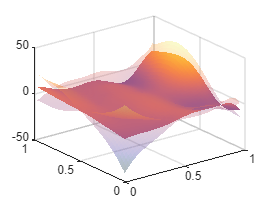

figure
utils.plotSurf(Z1,2,1)

tic
[Z2] = Z1.train2();
toc

Elapsed time is 9.995324 seconds.


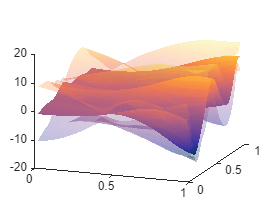

figure
hold on
utils.plotSurf(Z2,2,1)
view(20,20)

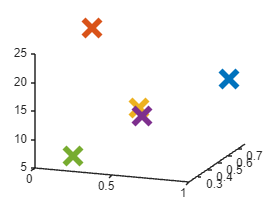

figure
hold on
tic
for i = 1:5
    [x{i},R{i}] = BO.argmax(@BO.maxVAR,Z2);
    plot3(x{i}(1),x{i}(2),R{i},'x','MarkerSize',18,'LineWidth',4)
end
view(20,20)

toc

Elapsed time is 0.549336 seconds.


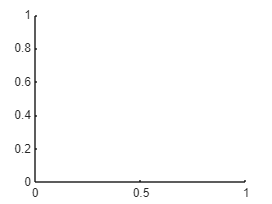

figure
hold on

tic
for i = 1:5
    [x{i},R{i}] = BO.argmin(@BO.EImin,Z2);
    plot3(x{i}(1),x{i}(2),R{i},'x','MarkerSize',18,'LineWidth',4)
end

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.

Error in kernels.Kernel/grad (line 154)
            dK = squeeze(reshape(dK,[a c b]));

Error in GP/eval_var (line 90)
                dksf = obj.kernel.grad(xs,xx

view(20,20)
toc